clear;
clc;

% Angles of attack.
alpha_list = [2 4 6];

% Mach numbers.
mach_list = [0.80 0.90 1.00 1.20 1.40];

% Legend line names.
annot_txt = ["$ \alpha = 2^{\circ} $", "$ \alpha = 4^{\circ} $", "$ \alpha = 6^{\circ} $"];

% Markers.
mks = {'o', '^', 'd'};

% Colors.
%   blue = "#1a53ff"; blue_light = "#9cd0ff";
%   green = "#00b300"; green_light = "#beffBe";
%   red = "#a3142f"; red_light = "#ff999a";
colors_dark = ["#1a53ff" "#00b300" "#a3142f"];
colors_light = ["#9cd0ff" "#beffBe" "#ff999a"];

avg_lift = zeros(size(alpha_list'*mach_list));
avg_drag = zeros(size(alpha_list'*mach_list));

% Loop over angles of attack.
for ia = 1:length(alpha_list)
    
    % Loop over Mach numbers get points.
    for im = 1:length(mach_list)

        [~,avg_lift(ia,im)] = import_aero(alpha_list(ia),mach_list(im),'lift','avg');
        [~,avg_drag(ia,im)] = import_aero(alpha_list(ia),mach_list(im),'drag','avg');
        
    end
end

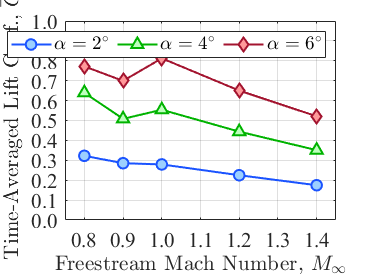

ax = axes;

% Axis bounds.
x_bounds = [min(mach_list)-0.05,max(mach_list)+0.05];
y_bounds = [0,1];

% Loop over angles to plot lines.
for ia = 1:length(alpha_list)
    hold on
    plot(mach_list,avg_lift(ia,:),LineWidth=1.5,Color=colors_dark(ia), ...
        Marker=mks{ia},MarkerSize=8, ...
        MarkerEdgeColor=colors_dark(ia),MarkerFaceColor=colors_light(ia));
    hold off
end

xticks(min(mach_list):0.1:max(mach_list));
xtickformat('%.1f');
yticks(0:0.10:1.00);
ytickformat('%.1f');
xlim(x_bounds);
ylim(y_bounds);
xlabel('Freestream Mach Number, $ M_{\infty} $',Interpreter='latex');
ylabel('Time-Averaged Lift Coef., $ \overline{C_{L}} $',Interpreter='latex');
box on;
grid on;
fontname(ax,'Times New Roman');
fontsize(ax,16,'points');
legend(annot_txt,Interpreter='latex',Location='north',NumColumns=3);

exportgraphics(gca,"C:\Users\jackh\OneDrive\MATLAB\aeroelasticity_research\onera-m6-modified\graphs\Mod. Winglet, Avg. Lift Coefficient.png",'Resolution',600)

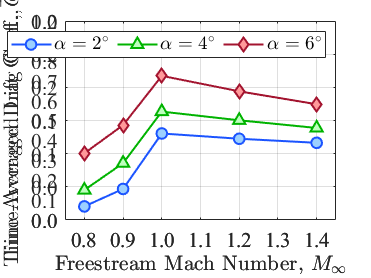

ax = axes;

% Axis bounds.
x_bounds = [min(mach_list)-0.05,max(mach_list)+0.05];
y_bounds = [0,0.24];

% Loop over angles to plot lines.
for ia = 1:length(alpha_list)
    hold on
    plot(mach_list,avg_drag(ia,:),LineWidth=1.5,Color=colors_dark(ia), ...
        Marker=mks{ia},MarkerSize=8, ...
        MarkerEdgeColor=colors_dark(ia),MarkerFaceColor=colors_light(ia));
    hold off
end

xticks(min(mach_list):0.1:max(mach_list));
xtickformat('%.1f');
yticks(0:0.04:0.24);
ytickformat('%.1f');
xlim(x_bounds);
ylim(y_bounds);
xlabel('Freestream Mach Number, $ M_{\infty} $',Interpreter='latex');
ylabel('Time-Averaged Drag Coef., $ \overline{C_{D}} $',Interpreter='latex');
box on;
grid on;
fontname(ax,'Times New Roman');
fontsize(ax,16,'points');
legend(annot_txt,Interpreter='latex',Location='north',NumColumns=3);

exportgraphics(gca,"C:\Users\jackh\OneDrive\MATLAB\aeroelasticity_research\onera-m6-modified\graphs\Mod. Winglet, Avg. Drag Coefficient.png",'Resolution',600)